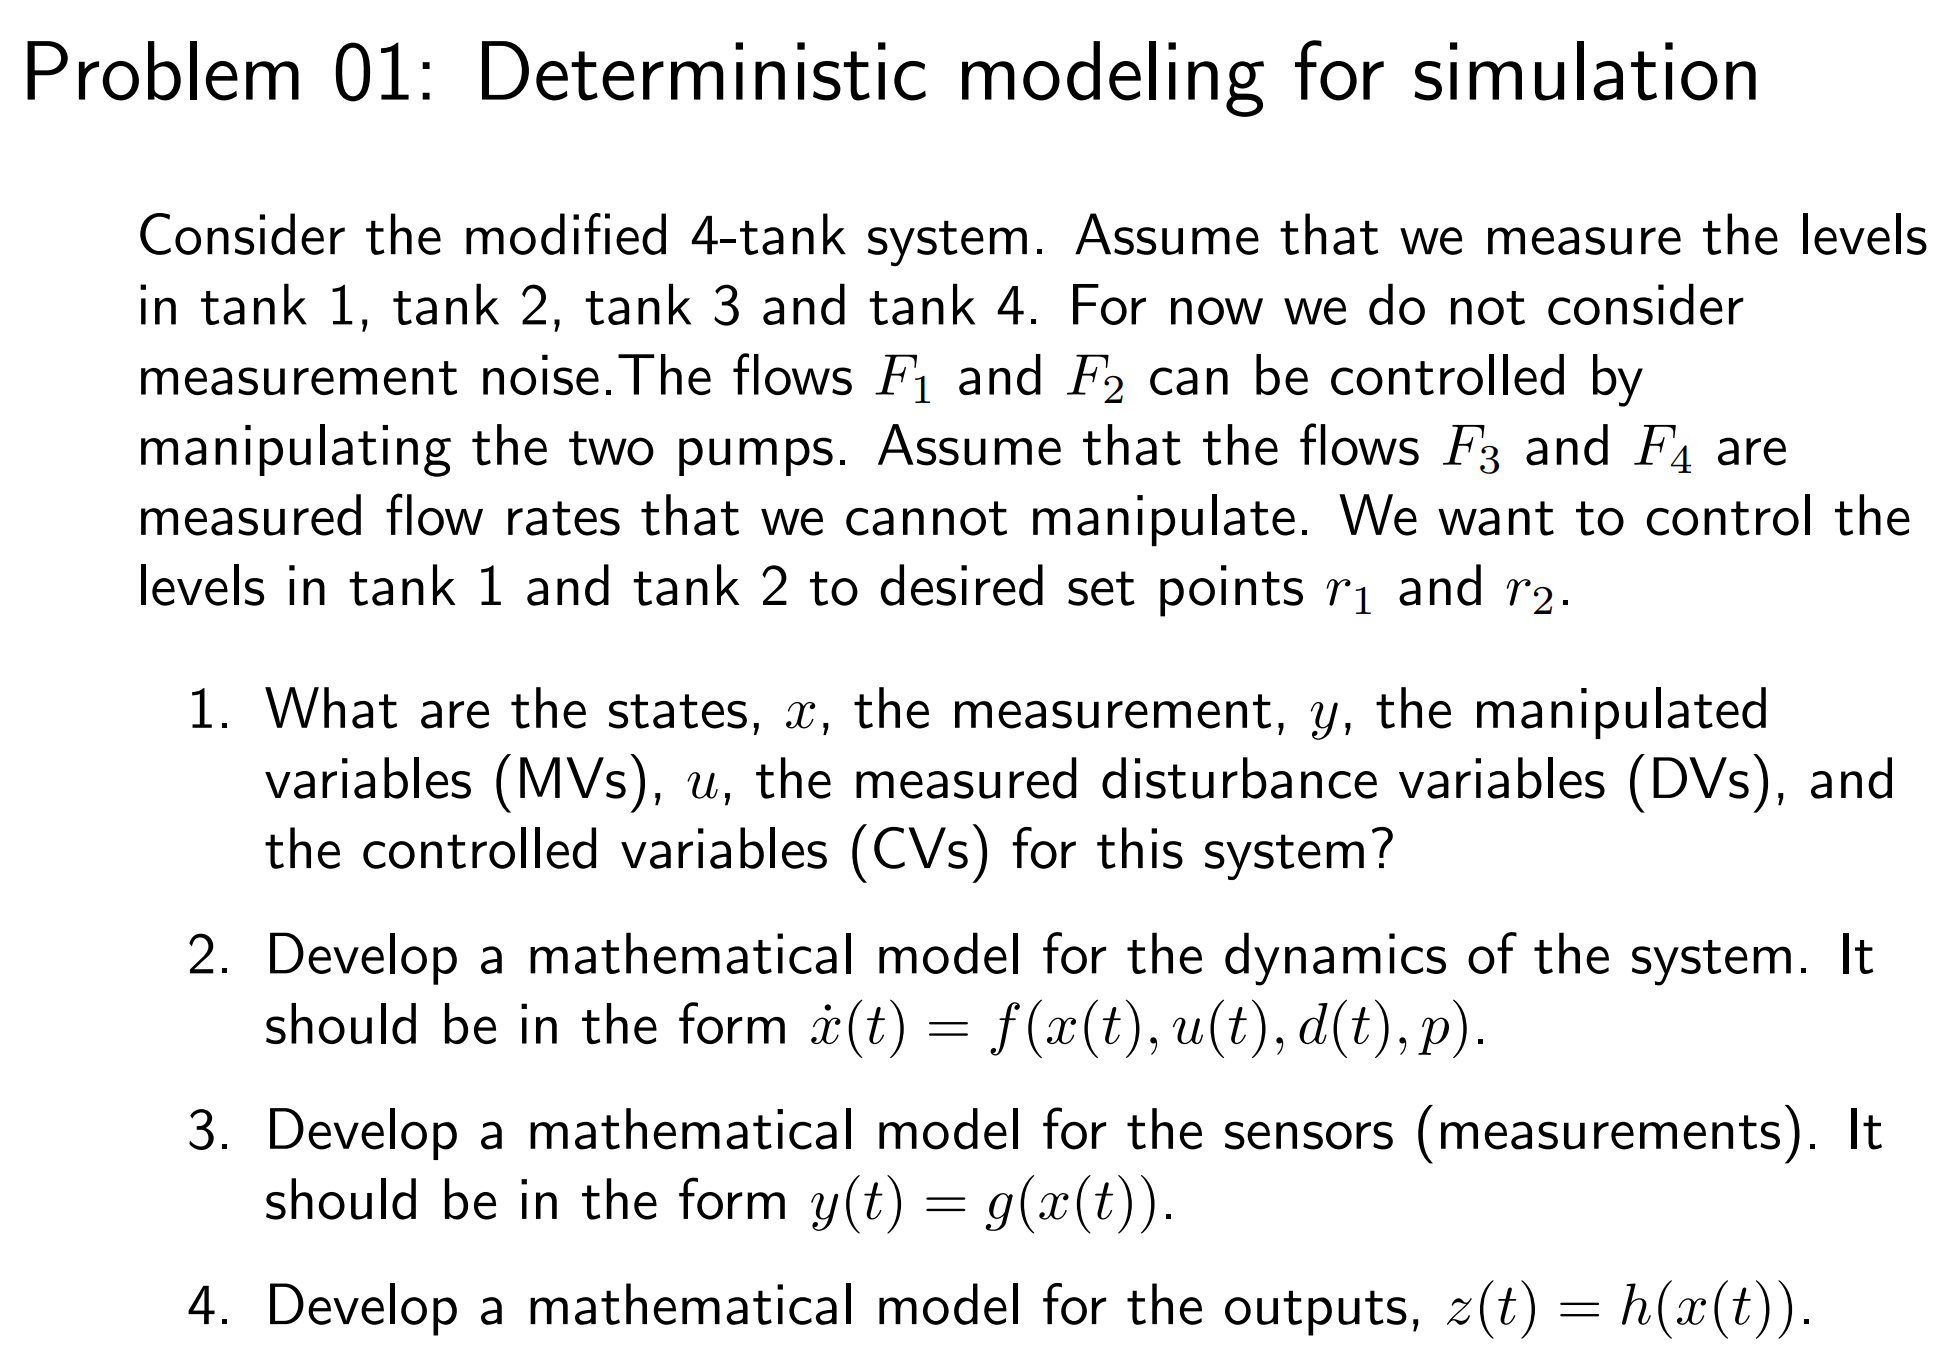

%same in ex3

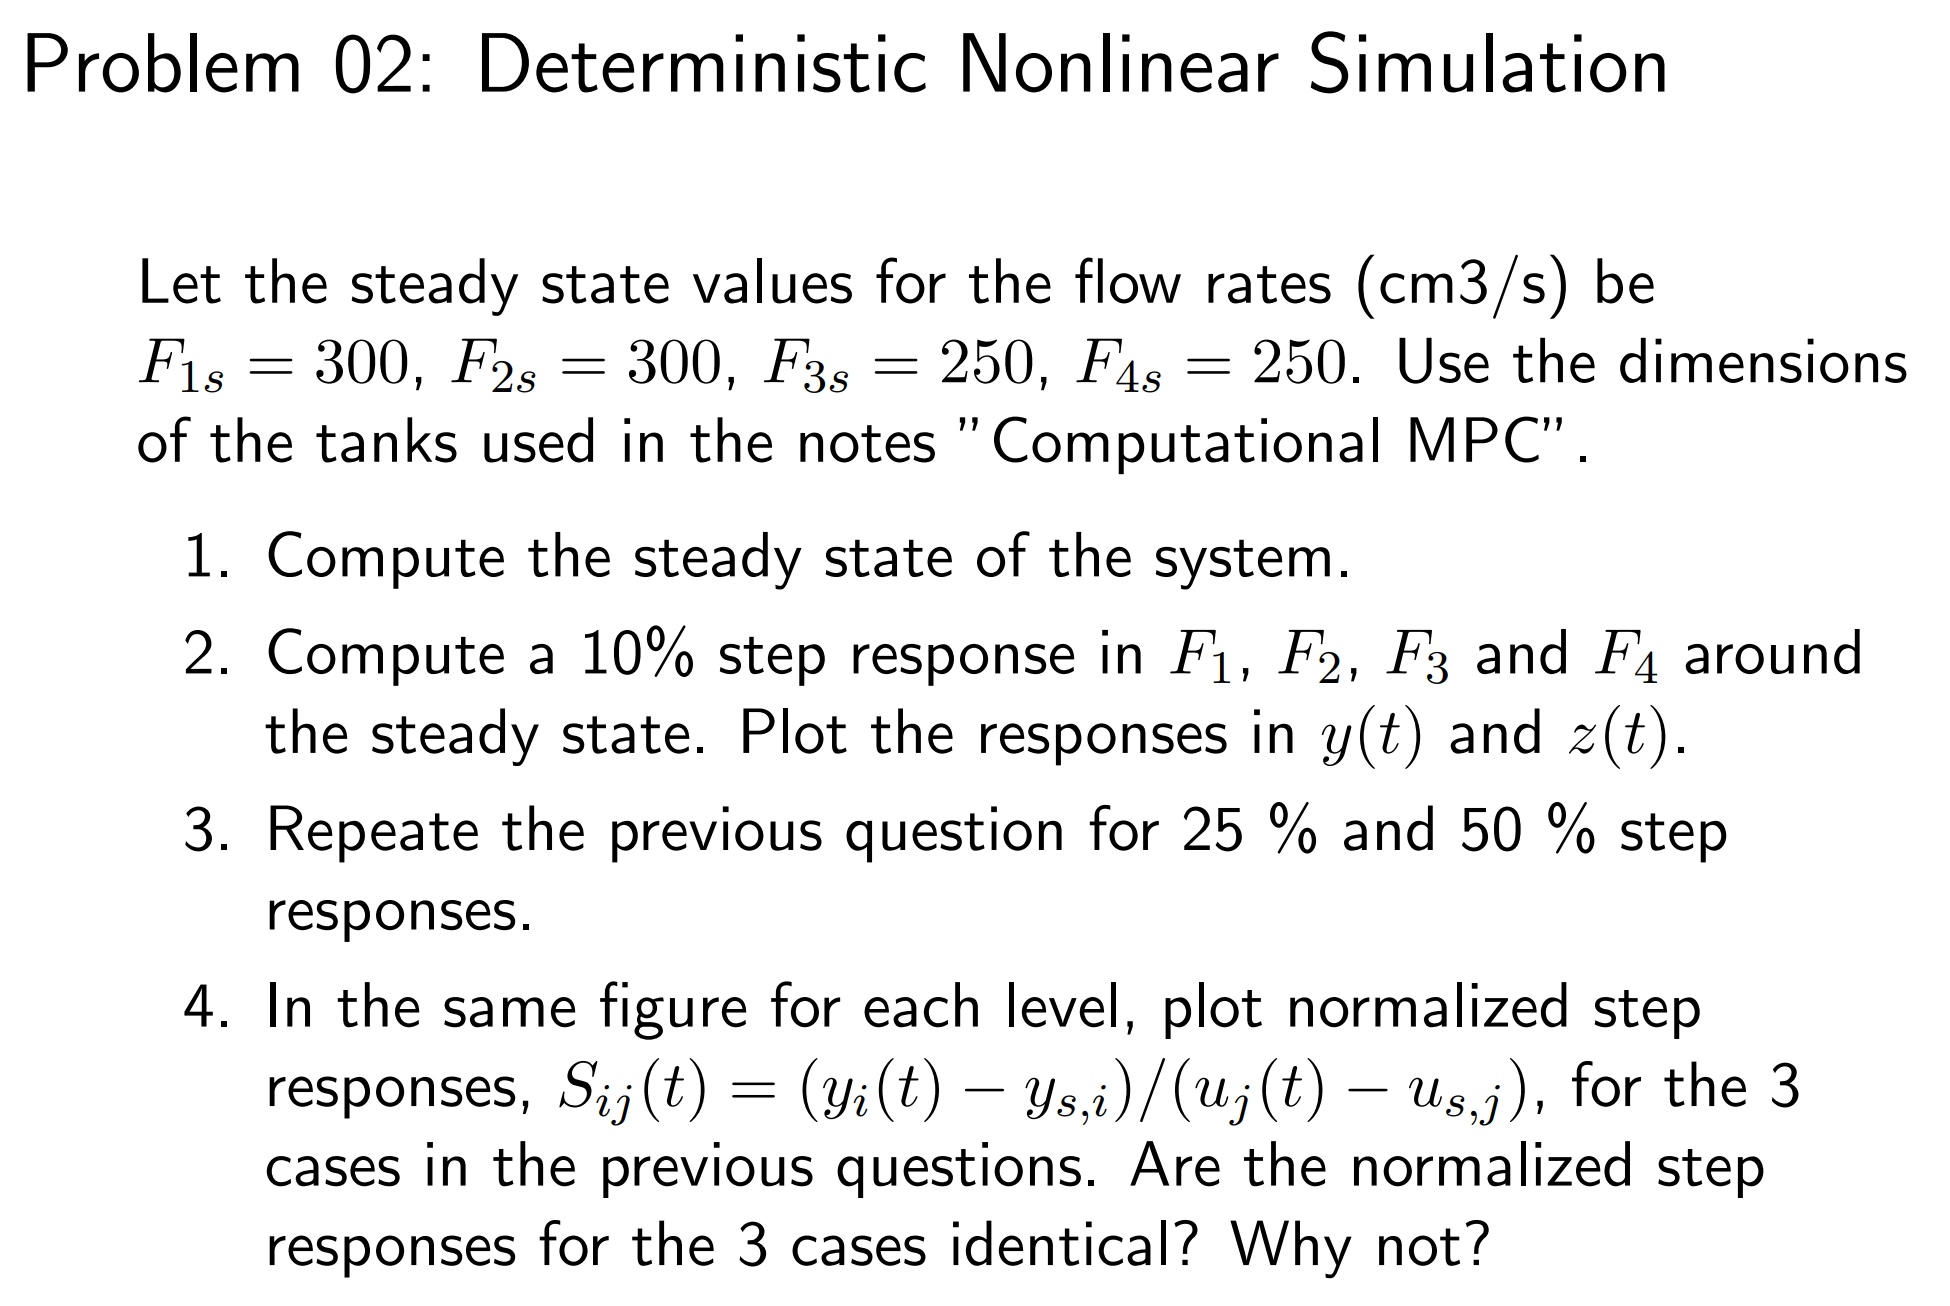

clear all;
% --------------------------------------------------------------
% Parameters
% --------------------------------------------------------------
a1 = 1.2272 %[cm2] Area of outlet pipe 1

a1 = 1.2272

a2 = 1.2272 %[cm2] Area of outlet pipe 2

a2 = 1.2272

a3 = 1.2272 %[cm2] Area of outlet pipe 3

a3 = 1.2272

a4 = 1.2272 %[cm2] Area of outlet pipe 4

a4 = 1.2272

A1 = 380.1327 %[cm2] Cross sectional area of tank 1

A1 = 380.1327

A2 = 380.1327 %[cm2] Cross sectional area of tank 2

A2 = 380.1327

A3 = 380.1327 %[cm2] Cross sectional area of tank 3

A3 = 380.1327

A4 = 380.1327 %[cm2] Cross sectional area of tank 4

A4 = 380.1327

gamma1 = 0.45; % Flow distribution constant. Valve 1
gamma2 = 0.40; % Flow distribution constant. Valve 2
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [a1; a2; a3; a4; A1; A2; A3; A4; gamma1; gamma2; g; rho];
% --------------------------------------------------------------

%ex4.2.1 找稳态点，求解非线性方程就可以了，所以使用了fsolve
ap = [a1; a2; a3; a4]; % [cm2] Pipe cross sectional areas
At = [A1; A2; A3; A4]; % [cm2] Tank cross sectional areas
gam = [gamma1; gamma2]; % [-] Valve constants
g = 981; %[cm/s2] The acceleration of gravity
rho = 1.00; %[g/cm3] Density of water
p = [ap; At; gam; g; rho];
% --------------------------------------------------------------
% Steady State
% --------------------------------------------------------------
F1=300;
F2=300;
F3=250;
F4=250;
us = [F1;F2]; % [cm3/s] Flow rates
ds = [F1;F2]; % [cm3/s] Flow rates
xs0 = [5000; 5000; 5000; 5000]; % [g] Initial guess on xs
xs = fsolve(@ModifiedFourTankSystemWrap,xs0,[],us,ds,p)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


xs = 	1.0e+04 *

    4.8658
    4.4027
    2.9641
    2.7817


ys = FourTankSystemSensor(xs,p)

ys =   128.0031
  115.8196
   77.9745
   73.1773


zs = FourTankSystemOutput(xs,p)

zs =   128.0031
  115.8196


%ex4.2.2 进行非线性系统的仿真，要用离散的仿真 这里我们每十秒一个区间进行仿真
%在平稳点附近 进行step xs为初值，us为初值
t0 = 0.0; % [s] Initial time
t_final = 20*60; % [s] Final time
Ts = 10; % [s] Sample Time
t = [t0:Ts:t_final]'; % [s] Sample instants
N = length(t);
m10 = 0; % [g] Liquid mass in tank 1 at time t0
m20 = 0; % [g] Liquid mass in tank 2 at time t0
m30 = 0; % [g] Liquid mass in tank 3 at time t0
m40 = 0; % [g] Liquid mass in tank 4 at time t0
x0=xs;
%step 0.1
u_10 = [repmat(F1,1,N); repmat(F2,1,N)];
u_10(1,40:end)=F1*(1+0.1);
d_10 = [repmat(F3,1,N); repmat(F4,1,N)];
%step 0.25
u_25 = [repmat([0],1,N); repmat([0],1,N)];
u_25(1,40:end)=F1*0.25;
% --------------------------------------------------------------
nx = 4; nu = 2; ny = 4; nz = 2;
x = zeros(nx,N);
y = zeros(ny,N);
z = zeros(nz,N);
X = zeros(0,nx);
T = zeros(0,1);
x(:,1) = x0;
for k = 1:N-1
y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function
[Tk,Xk] = ode15s(@ModifiedFourTankSystem,[t(k) t(k+1)],x(:,k),[],...
u_10(:,k),d_10(:,k),p);
x(:,k+1) = Xk(end,:)';
T = [T; Tk];
X = [X; Xk];
end
k = N;
y(:,k) = FourTankSystemSensor(x(:,k),p); % Sensor function
z(:,k) = FourTankSystemOutput(x(:,k),p); % Output function

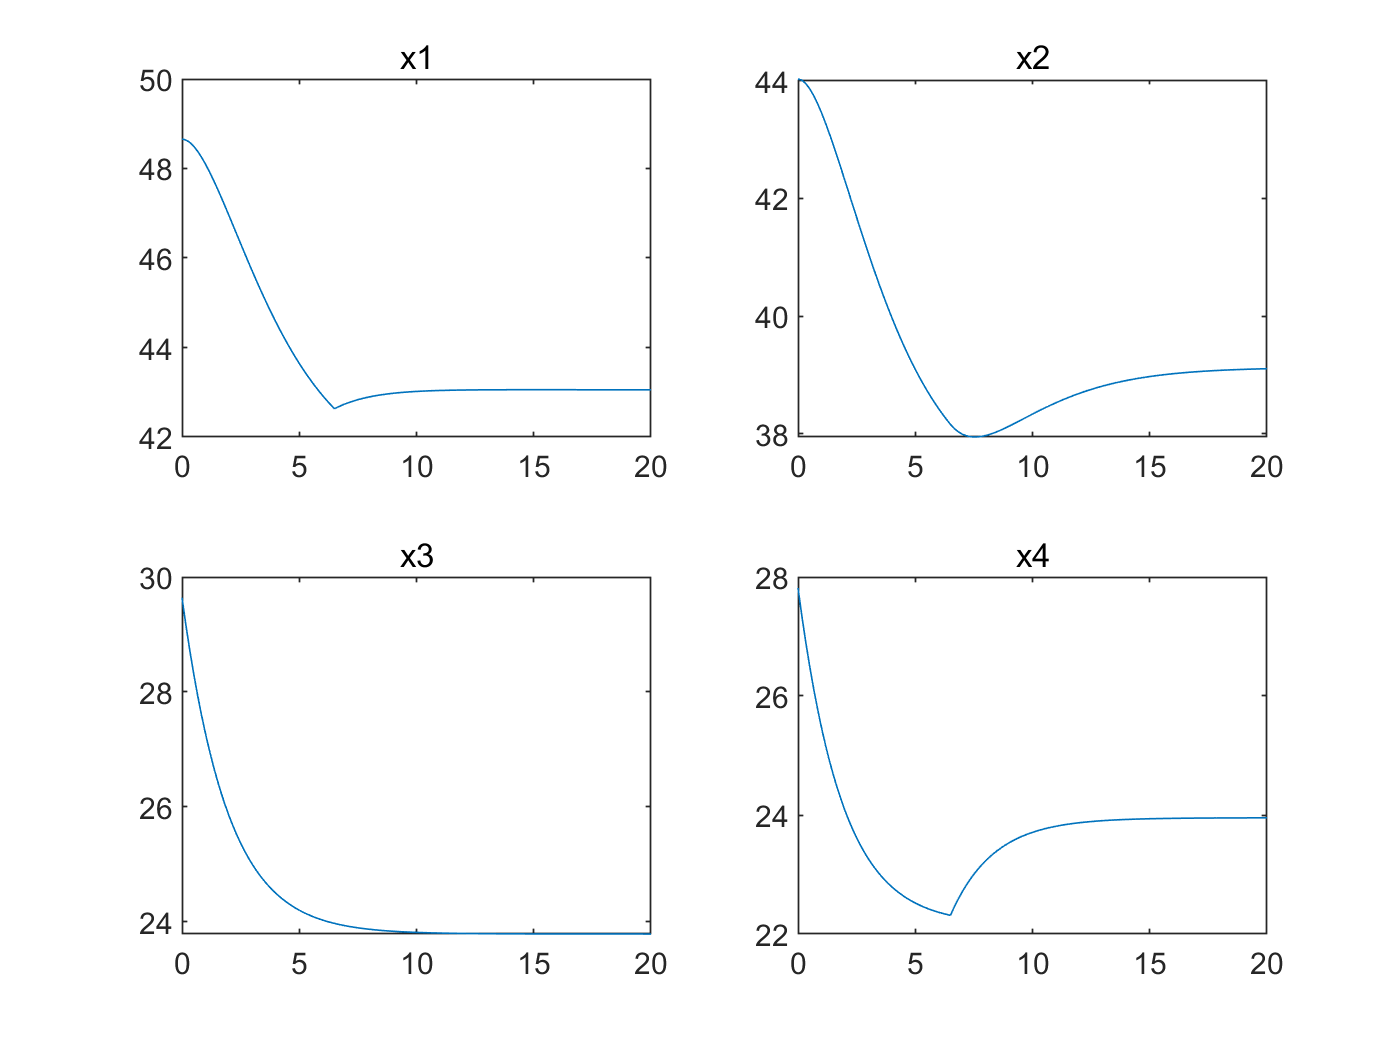

%ex4.2.2 plot x 
figure
subplot(2,2,1)
plot(t/60,x(1,:)/1e3)
title('x1')
subplot(2,2,2)
plot(t/60,x(2,:)/1e3)
title('x2')
subplot(2,2,3)
plot(t/60,x(3,:)/1e3)
title('x3')
subplot(2,2,4)
plot(t/60,x(4,:)/1e3)
title('x4')

%ex4.2.4 计算相对变化的step响应
size_col=size(x,2);
s=zeros(1,size_col)

s =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


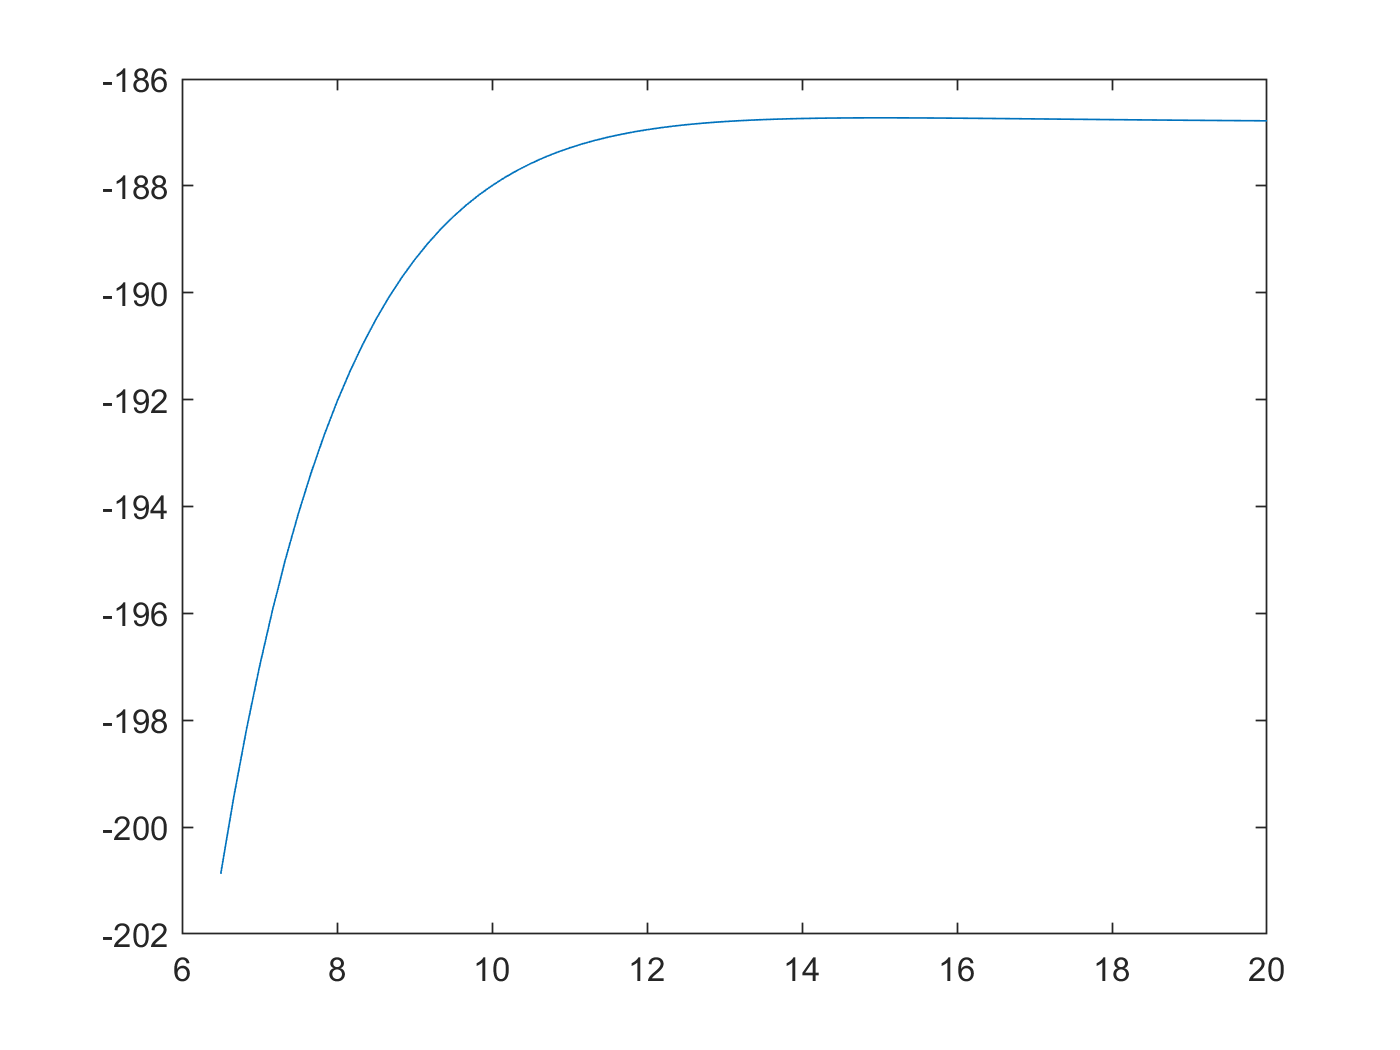

for i=1:size_col
    s(i)=(x(1,i)-xs(1))/(u_10(1,i)-us(1));
end
figure
plot(t/60,s)

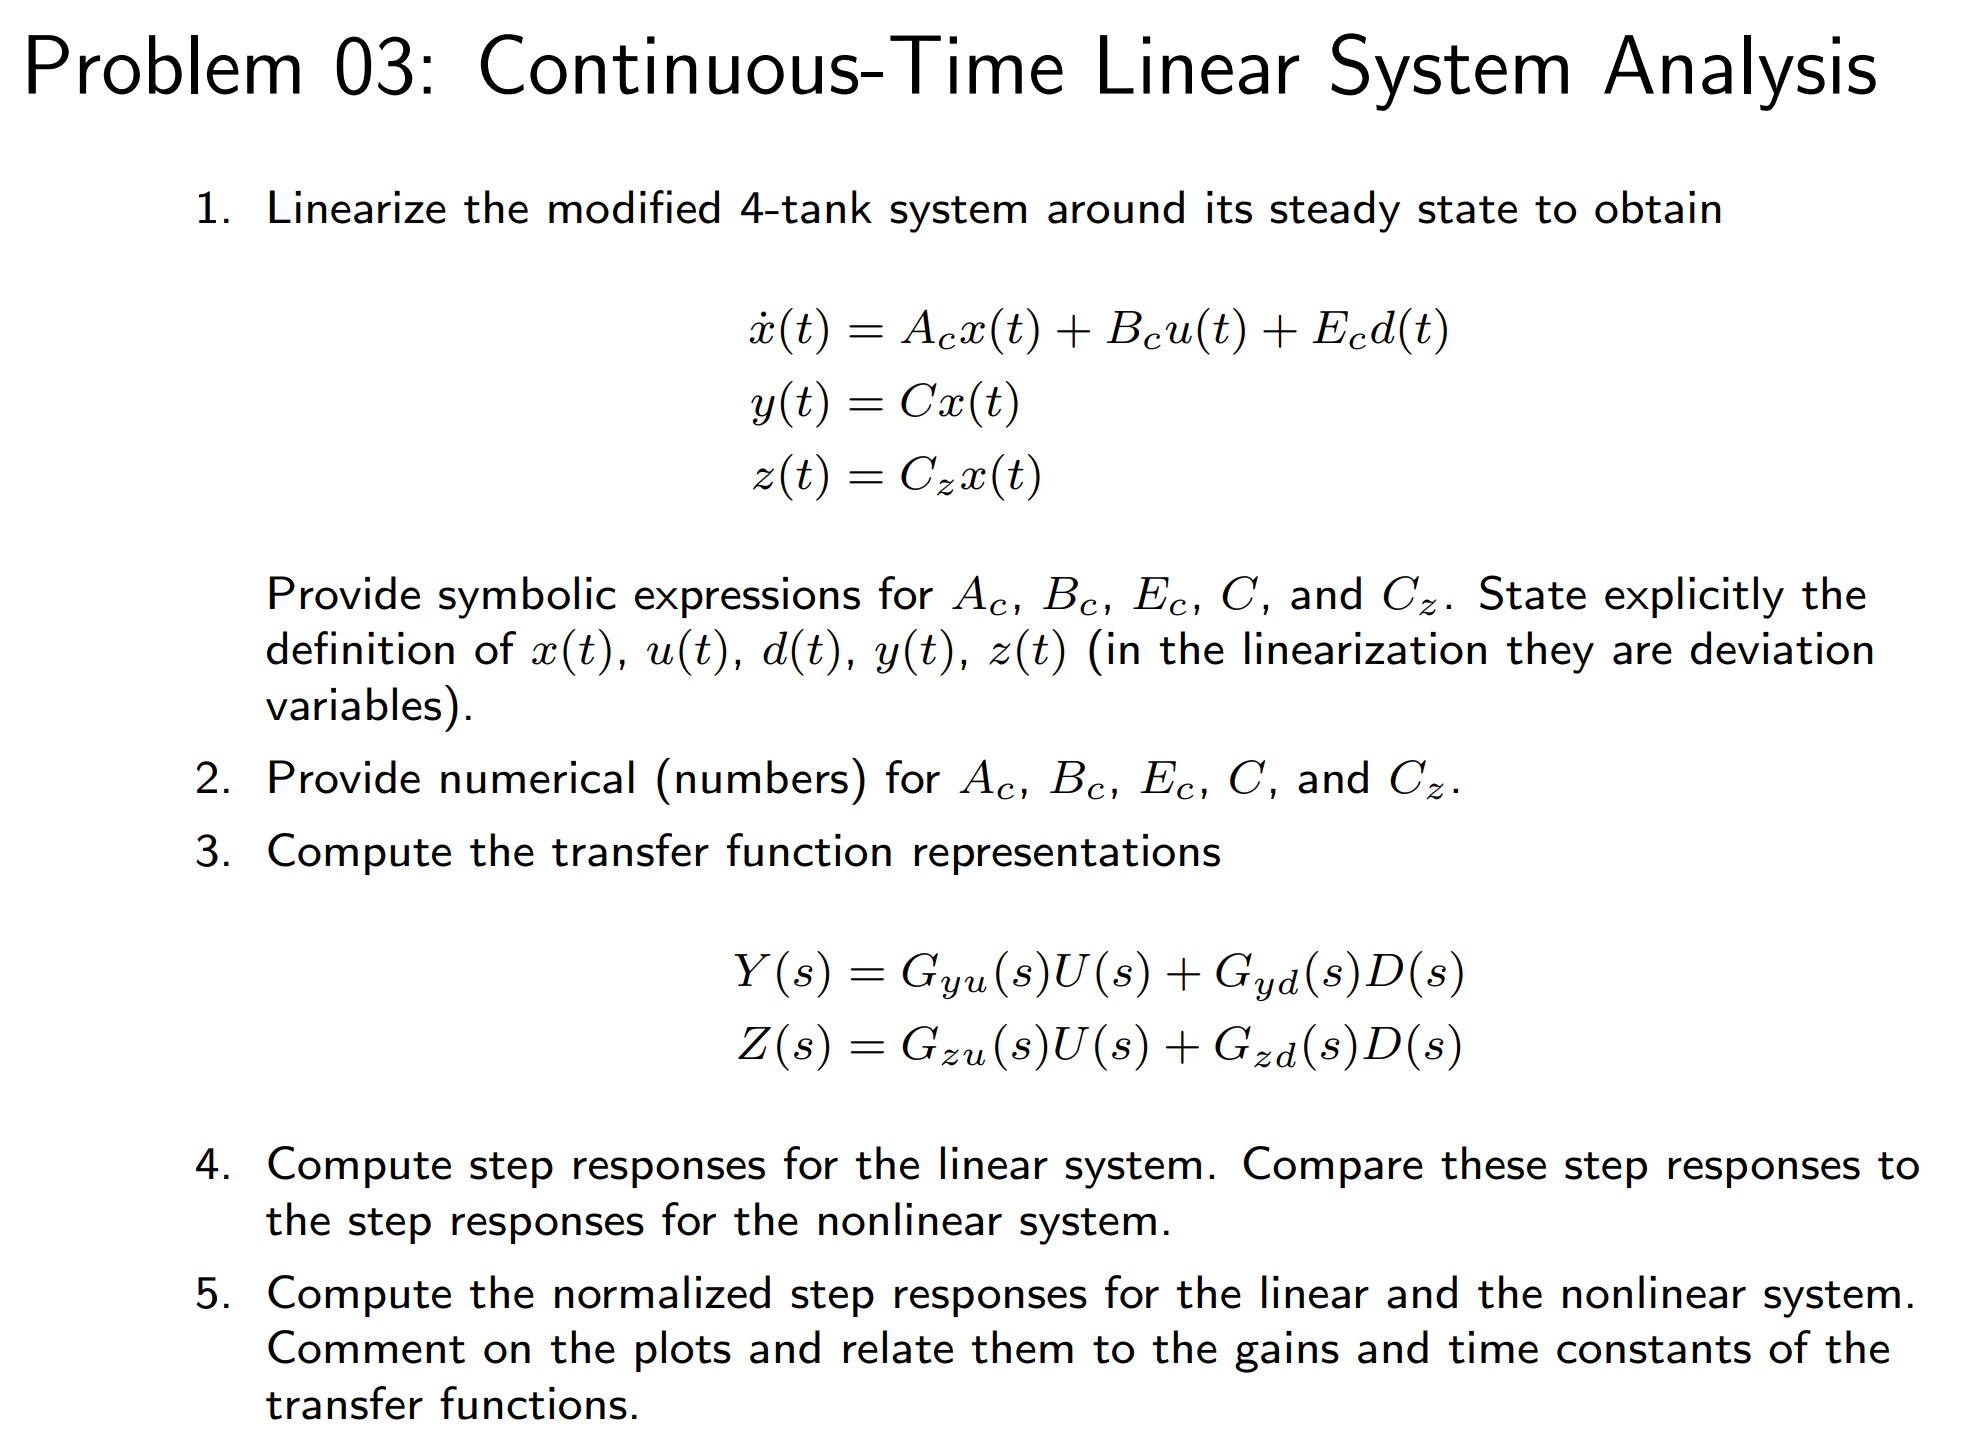

%ex4.3.1 对非线性系统进行线性化，需要使用雅可比矩阵求导
syms x1 x2 x3 x4 u1 u2 d1 d2
m = [x1;x2;x3;x4]; % Mass of liquid in each tank [g]
F = [u1;u2;d1;d2]; % Flow rates in pumps [cm3/s]
a = p(1:4,1); % Pipe cross sectional areas [cm2]
A = p(5:8,1); % Tank cross sectional areas [cm2]
gamma = p(9:10,1); % Valve positions [-]
g = p(11,1); % Acceleration of gravity [cm/s2]
rho = p(12,1); % Density of water [g/cm3]

% Inflows

qin(1,1) = gamma(1)*F(1); % Inflow from valve 1 to tank 1 [cm3/s]
qin(2,1) = gamma(2)*F(2); % Inflow from valve 2 to tank 2 [cm3/s]
qin(3,1) = (1-gamma(2))*F(2); % Inflow from valve 2 to tank 3 [cm3/s]
qin(4,1) = (1-gamma(1))*F(1); % Inflow from valve 1 to tank 4 [cm3/s]
% Out_finallows
h = m./(rho*A); % Liquid level in each tank [cm]
qout = a.*sqrt(2*g*h); % Out_finallow from each tank [cm3/s]
% Differential equations

fx(1,1) = rho*(qin(1,1)+qout(3,1)-qout(1,1)); % Mass balance Tank 1
fx(2,1) = rho*(qin(2,1)+qout(4,1)-qout(2,1)); % Mass balance Tank 2
fx(3,1) = rho*(qin(3,1)-qout(3,1))+F(3); % Mass balance Tank 3
fx(4,1) = rho*(qin(4,1)-qout(4,1))+F(4); % Mass balance Tank 4
gx = zeros(4,1);
gx = m./(rho*A);% Liquid level in each tank [cm]
Ass=eval(vpa(subs(jacobian(fx,m),[m;F],[xs;us;ds]),4))

Ass =    -0.0063         0    0.0081         0
         0   -0.0066         0    0.0084
         0         0   -0.0081         0
         0         0         0   -0.0084


Bss=eval(vpa(subs(jacobian(fx,F(1:2)),[m;F],[xs;us;ds]),4))

Bss =     0.4500         0
         0    0.4000
         0    0.6000
    0.5500         0


Bdss=eval(vpa(subs(jacobian(fx,F(3:4)),[m;F],[xs;us;ds]),4))

Bdss =      0     0
     0     0
     1     0
     0     1


Css=eval(vpa(subs(jacobian(gx,m),[m;F],[xs;us;ds]),4))

Css =     0.0026         0         0         0
         0    0.0026         0         0
         0         0    0.0026         0
         0         0         0    0.0026


Dss=eval(vpa(subs(jacobian(gx,F(1:2)),[m;F],[xs;us;ds]),4))

Dss =      0     0
     0     0
     0     0
     0     0